# **整体优化**

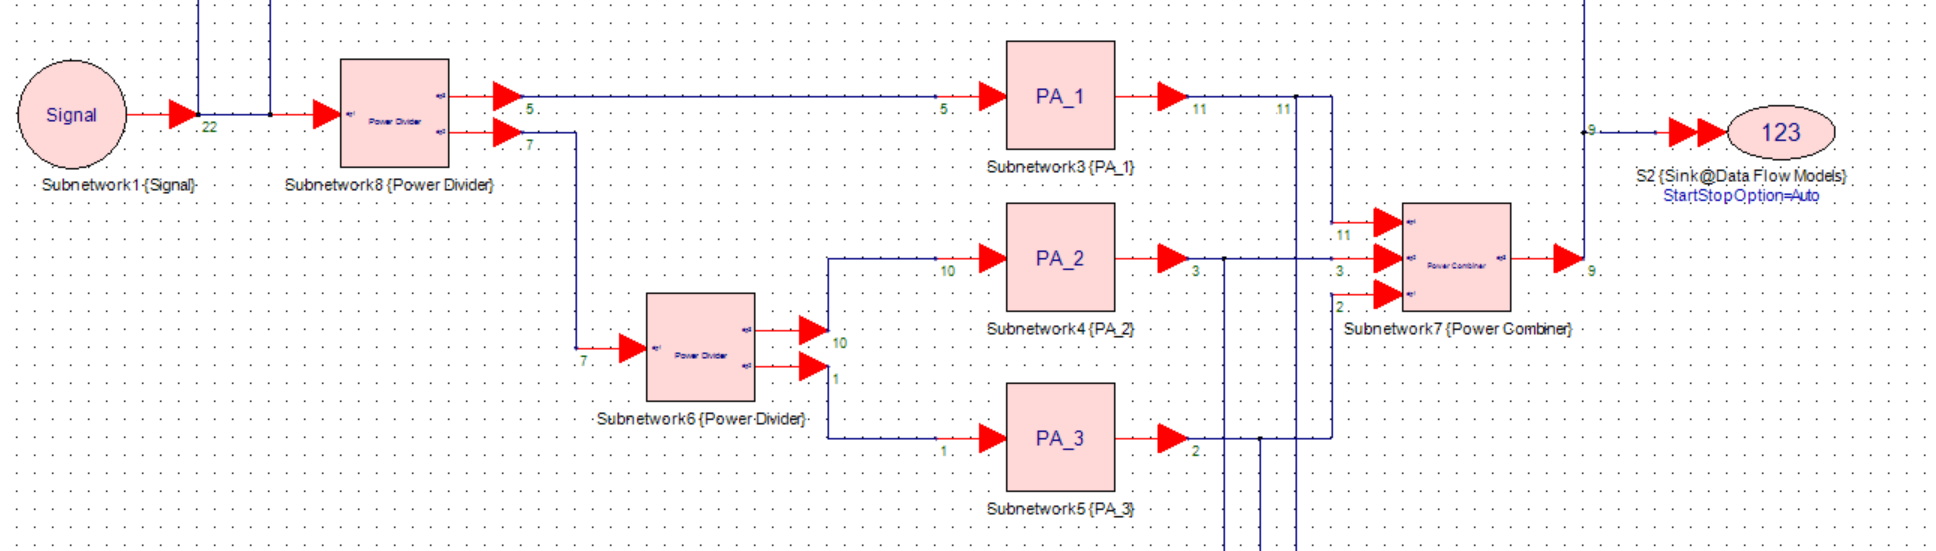

% 运行前请先将子文件夹添加到路径
clc;

## -----------------------------Model A Train----------------------------

## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Train();
% 根据需要选取原始数据
numStart = 1000;
numEnd = 3010;
dim = numEnd-numStart;
Sys_input = Data_matrix(numStart+1:numEnd,1) + 1i * Data_matrix(numStart+1:numEnd,2);
Sys_output = Data_matrix(numStart+1:numEnd,end-1) + 1i * Data_matrix(numStart+1:numEnd,end);
% 参数需要保持一致
M = 4;
path = 'Method_A\Whole\Transformer_simple.mat';
Train_flag = 0;

## 【训练】整体训练

% 模型训练
if (Train_flag)
    model=Transformer_simple(M,dim,Sys_input,Sys_output);
    save(path, 'model');
end
% 模型精度
[model_input,model_output] = pre_train(M,Sys_input,Sys_output,dim);
data = load(path);
DPD_output_m = predict(data.model,model_input);
DPD_output = DPD_output_m(1,:)+1j*DPD_output_m(2,:);
nmse = NMSE_dB(model_output(1,:)+1j*model_output(2,:), DPD_output);
fprintf('模型的拟合精度NMSE为 %f dB\n', nmse);

模型的拟合精度NMSE为 -28.096169 dB


## Model Test

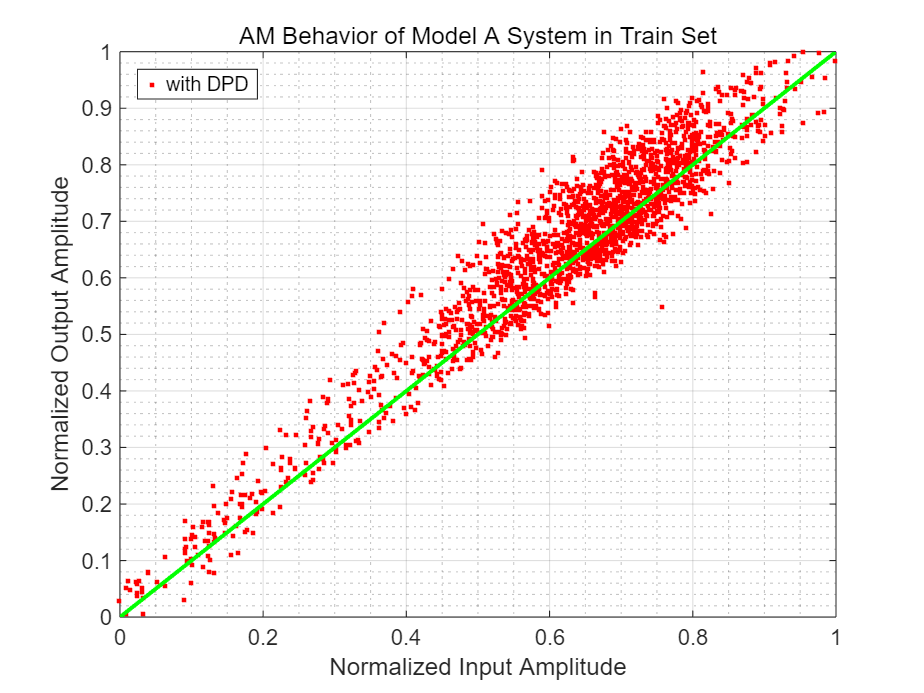

% 模型仿真
Sys_input_DPD=DPD_predict(Sys_input,M,path);
[A1_input,A23] = Power_Divider(Sys_input_DPD);
[A2_input,A3_input] = Power_Divider(A23);
A1_output = PA_1(A1_input);
A2_output = PA_2(A2_input);
A3_output = PA_3(A3_input);
Sys_output = Power_Combiner(A1_output,A2_output,A3_output);
% 性能评估
Plot_AM(Sys_input,Sys_output,'AM Behavior of Model A System in Train Set','with DPD');

nmse= NMSE_dB(Sys_input,Sys_output);
fprintf('使用Model A，系统的NMSE(Train)仿真结果为 %f dB\n', nmse);

使用Model A，系统的NMSE(Train)仿真结果为 -25.922682 dB


## -----------------------------Model A Valid----------------------------

## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Valid();
% 根据需要选取原始数据
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2);
% 参数需要保持一致
M = 4;
path = 'Method_A\Whole\Transformer_simple.mat';

## Model Test

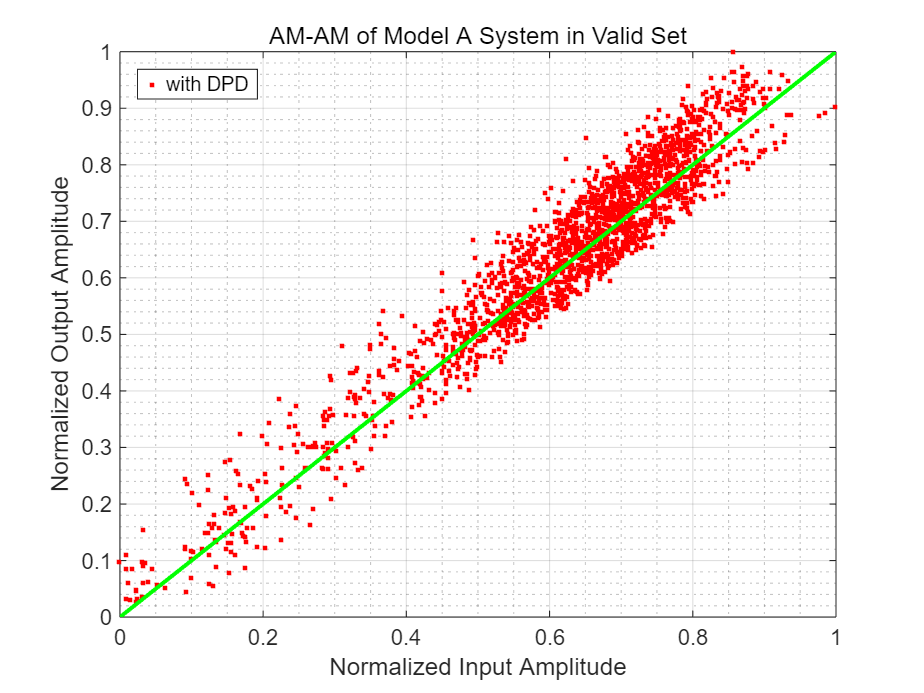

% 模型仿真
Sys_input_DPD=DPD_predict(Sys_input,M,path);
[A1_input,A23] = Power_Divider(Sys_input_DPD);
[A2_input,A3_input] = Power_Divider(A23);
A1_output = PA_1(A1_input);
A2_output = PA_2(A2_input);
A3_output = PA_3(A3_input);
Sys_output = Power_Combiner(A1_output,A2_output,A3_output);
% 由于PA和DPD的延时，所以少算（4+M）个值
Sys_input = Sys_input(5+M:end);
Sys_output = Sys_output(5+M:end);
% 性能评估
Plot_AM(Sys_input,Sys_output,'AM-AM of Model A System in Valid Set','with DPD');

nmse= NMSE_dB(Sys_input,Sys_output);
fprintf('使用Model A，系统的NMSE(Valid)仿真结果为 %f dB\n', nmse);

使用Model A，系统的NMSE(Valid)仿真结果为 -26.051169 dB
